# Motor Torque Sizing based on the Joint Angle data of the Right Leg exoskeleton

clear
close all
clc


Initialization of the respective joint angles

syms tau_ankle tau_knee tau_hip real

g = 9.807

g = 9.8070

m_thigh = 11

m_thigh = 11

m_leg = 5.115

m_leg = 5.1150

m_foot = 1.595

m_foot = 1.5950


l_fl = .2432

l_fl = 0.2432

l_foot = 0.0624

l_foot = 0.0624

l_leg = 0.3936

l_leg = 0.3936

l_thigh = 0.392

l_thigh = 0.3920



time_period = 0:1:99

time_period =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


theta_1 = zeros(1,100)

theta_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


theta_2 = zeros(1,100)

theta_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


theta_3 = linspace(20, 40, 100)

theta_3 =    20.0000   20.2020   20.4040   20.6061   20.8081   21.0101   21.2121   21.4141   21.6162   21.8182   22.0202   22.2222   22.4242   22.6263   22.8283   23.0303   23.2323   23.4343   23.6364   23.8384   24.0404   24.2424   24.4444   24.6465   24.8485   25.0505   25.2525   25.4545   25.6566   25.8586   26.0606   26.2626   26.4646   26.6667   26.8687   27.0707   27.2727   27.4747   27.6768   27.8788   28.0808   28.2828   28.4848   28.6869   28.8889   29.0909   29.2929   29.4949   29.6970   29.8990


tau_ankle = m_foot*g*cos(theta_3)*(l_fl/2)

tau_ankle =     0.7762    0.4120    0.0310   -0.3512   -0.7192   -1.0579   -1.3535   -1.5941   -1.7699   -1.8737   -1.9013   -1.8515   -1.7265   -1.5312   -1.2736   -0.9643   -0.6157   -0.2421    0.1414    0.5191    0.8757    1.1967    1.4690    1.6816    1.8258    1.8957    1.8885    1.8044    1.6470    1.4226    1.1404    0.8117    0.4501    0.0701   -0.3127   -0.6828   -1.0251   -1.3258   -1.5725   -1.7552   -1.8666   -1.9020   -1.8601   -1.7425   -1.5541   -1.3024   -0.9978   -0.6525   -0.2808    0.1024


tau_knee = m_leg*g*sin(theta_2)*(l_leg/2) + m_foot*g*(l_leg*sin(theta_2) + cos(theta_3)*(l_fl/2))

tau_knee =     0.7762    0.4120    0.0310   -0.3512   -0.7192   -1.0579   -1.3535   -1.5941   -1.7699   -1.8737   -1.9013   -1.8515   -1.7265   -1.5312   -1.2736   -0.9643   -0.6157   -0.2421    0.1414    0.5191    0.8757    1.1967    1.4690    1.6816    1.8258    1.8957    1.8885    1.8044    1.6470    1.4226    1.1404    0.8117    0.4501    0.0701   -0.3127   -0.6828   -1.0251   -1.3258   -1.5725   -1.7552   -1.8666   -1.9020   -1.8601   -1.7425   -1.5541   -1.3024   -0.9978   -0.6525   -0.2808    0.1024


tau_hip = m_thigh*g*sin(theta_1)*(l_thigh/2) + m_leg*g*(l_thigh*sin(theta_1) + sin(theta_2)*(l_leg/2)) + m_foot*g*(l_thigh*sin(theta_1) + l_leg*sin(theta_2) + cos(theta_3)*(l_fl/2))

tau_hip =     0.7762    0.4120    0.0310   -0.3512   -0.7192   -1.0579   -1.3535   -1.5941   -1.7699   -1.8737   -1.9013   -1.8515   -1.7265   -1.5312   -1.2736   -0.9643   -0.6157   -0.2421    0.1414    0.5191    0.8757    1.1967    1.4690    1.6816    1.8258    1.8957    1.8885    1.8044    1.6470    1.4226    1.1404    0.8117    0.4501    0.0701   -0.3127   -0.6828   -1.0251   -1.3258   -1.5725   -1.7552   -1.8666   -1.9020   -1.8601   -1.7425   -1.5541   -1.3024   -0.9978   -0.6525   -0.2808    0.1024


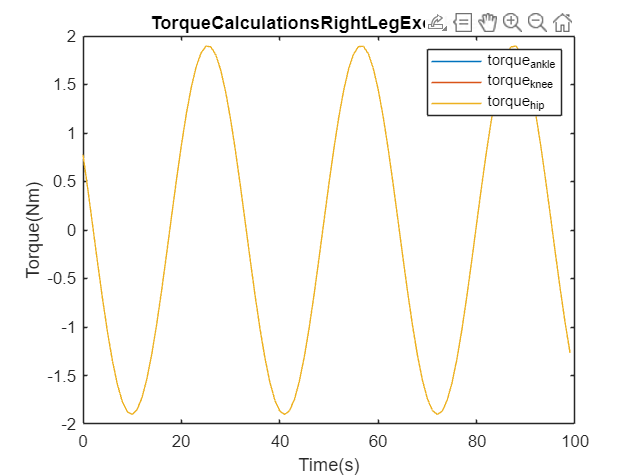

plot(time_period, tau_ankle)
hold on
plot(time_period, tau_knee)
plot(time_period, tau_hip)

legend(["torque_ankle","torque_knee","torque_hip"])

title("TorqueCalculationsRightLegExoskeleton")
xlabel("Time(s)")
ylabel("Torque(Nm)")